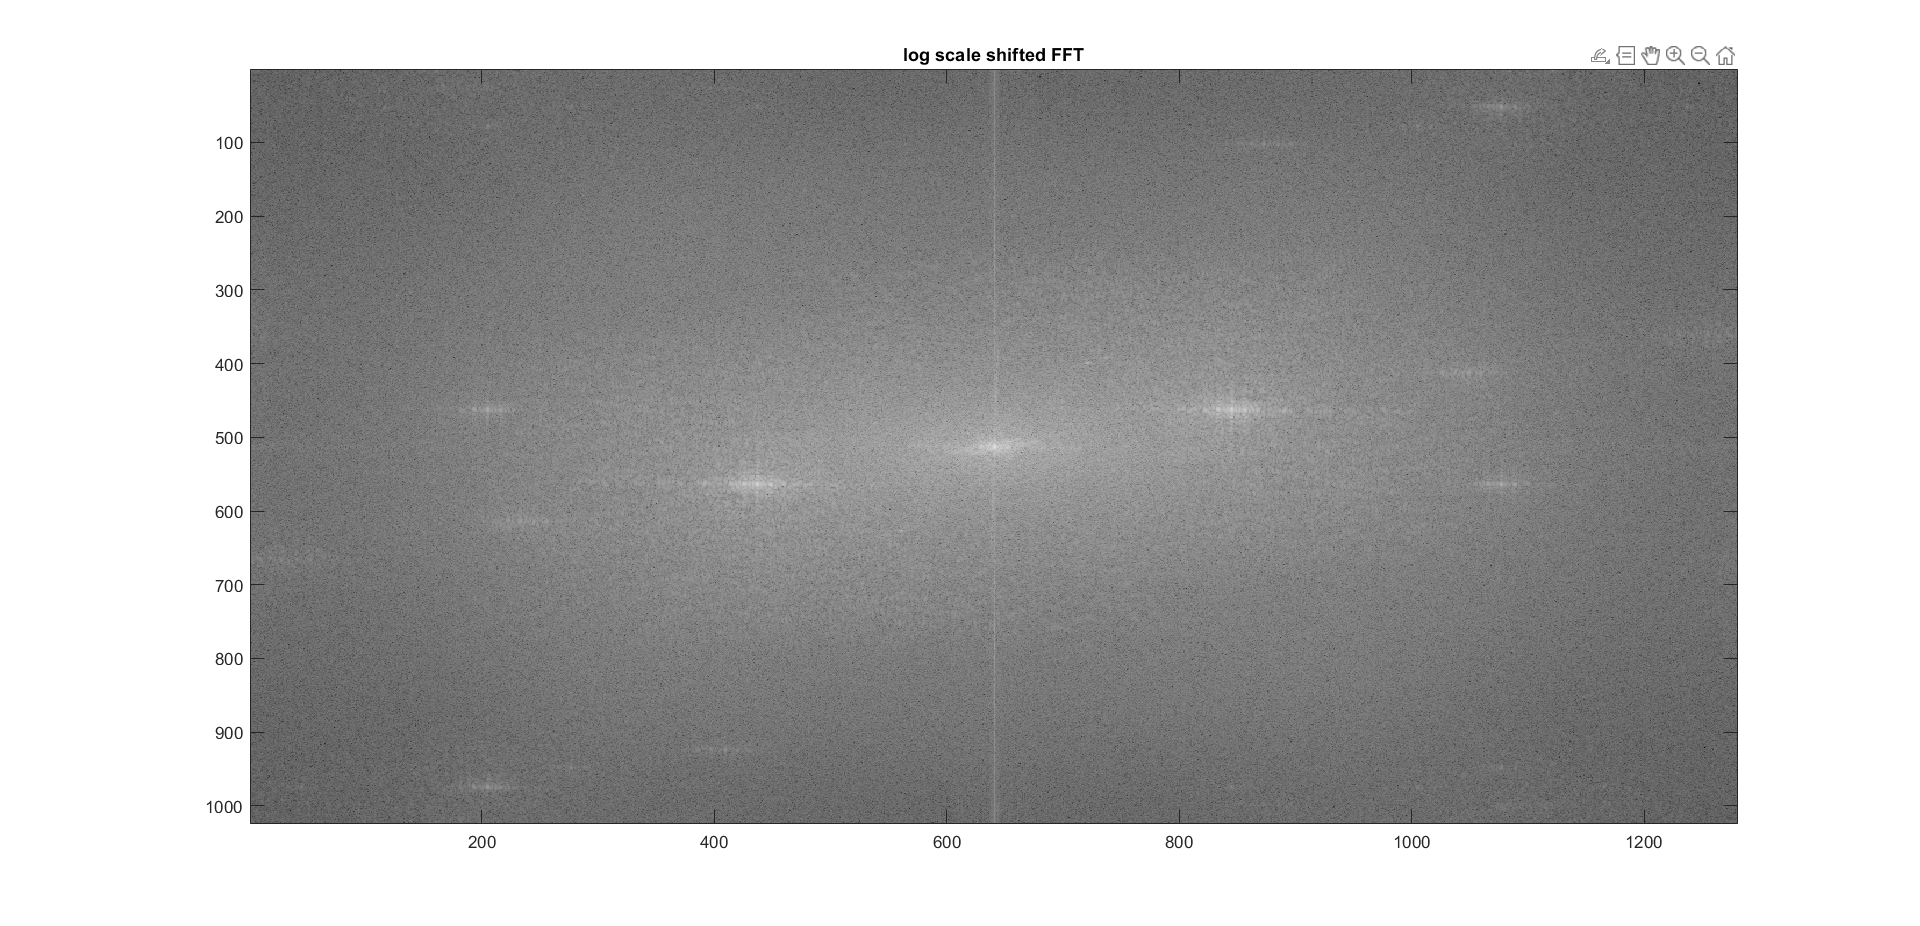

clear; close;
%loading image 
I = rgb2gray(imread("digitalholographysample.jpg"));

%taking FFT and fftshift 
Ifft = fftshift(fft2(double(I)));
figure; 
imagesc(log(abs(Ifft))); colormap gray; title("log scale shifted FFT"); 
%Crop out one of the patterns
[J, rectout] = imcrop;


%Extracting actual FT from the FT image
Ifft_abs = imcrop(abs(Ifft), rectout);
Ifft_ang = imcrop(angle(Ifft), rectout);

%matrix containing size of I
% s = (height, width)
s = size(I);
I_width = s(2); %image width 
I_height = s(1); %image height

%two matrix the same size as I 
mat_abs = zeros(s);
mat_ang = zeros(s);

%extracting width and height of rectout 
%rounding to a whole number 
cropped_width = round(rectout(3));
cropped_height = round(rectout(4));

%calculating starting row and column 
start_row = round(I_height/2 - cropped_height/2);
start_column = round(I_width/2 - cropped_width/2);

%assigning center position 
mat_abs(start_row:start_row+cropped_height-1, start_column:start_column+cropped_width-1) = Ifft_abs;
mat_ang(start_row:start_row+cropped_height-1, start_column:start_column+cropped_width-1) = Ifft_ang;

%blank matrix 
MAT = mat_abs .* exp(1j .* mat_ang);

%inverse FFT 
Ifft_inv = ifft2(MAT);

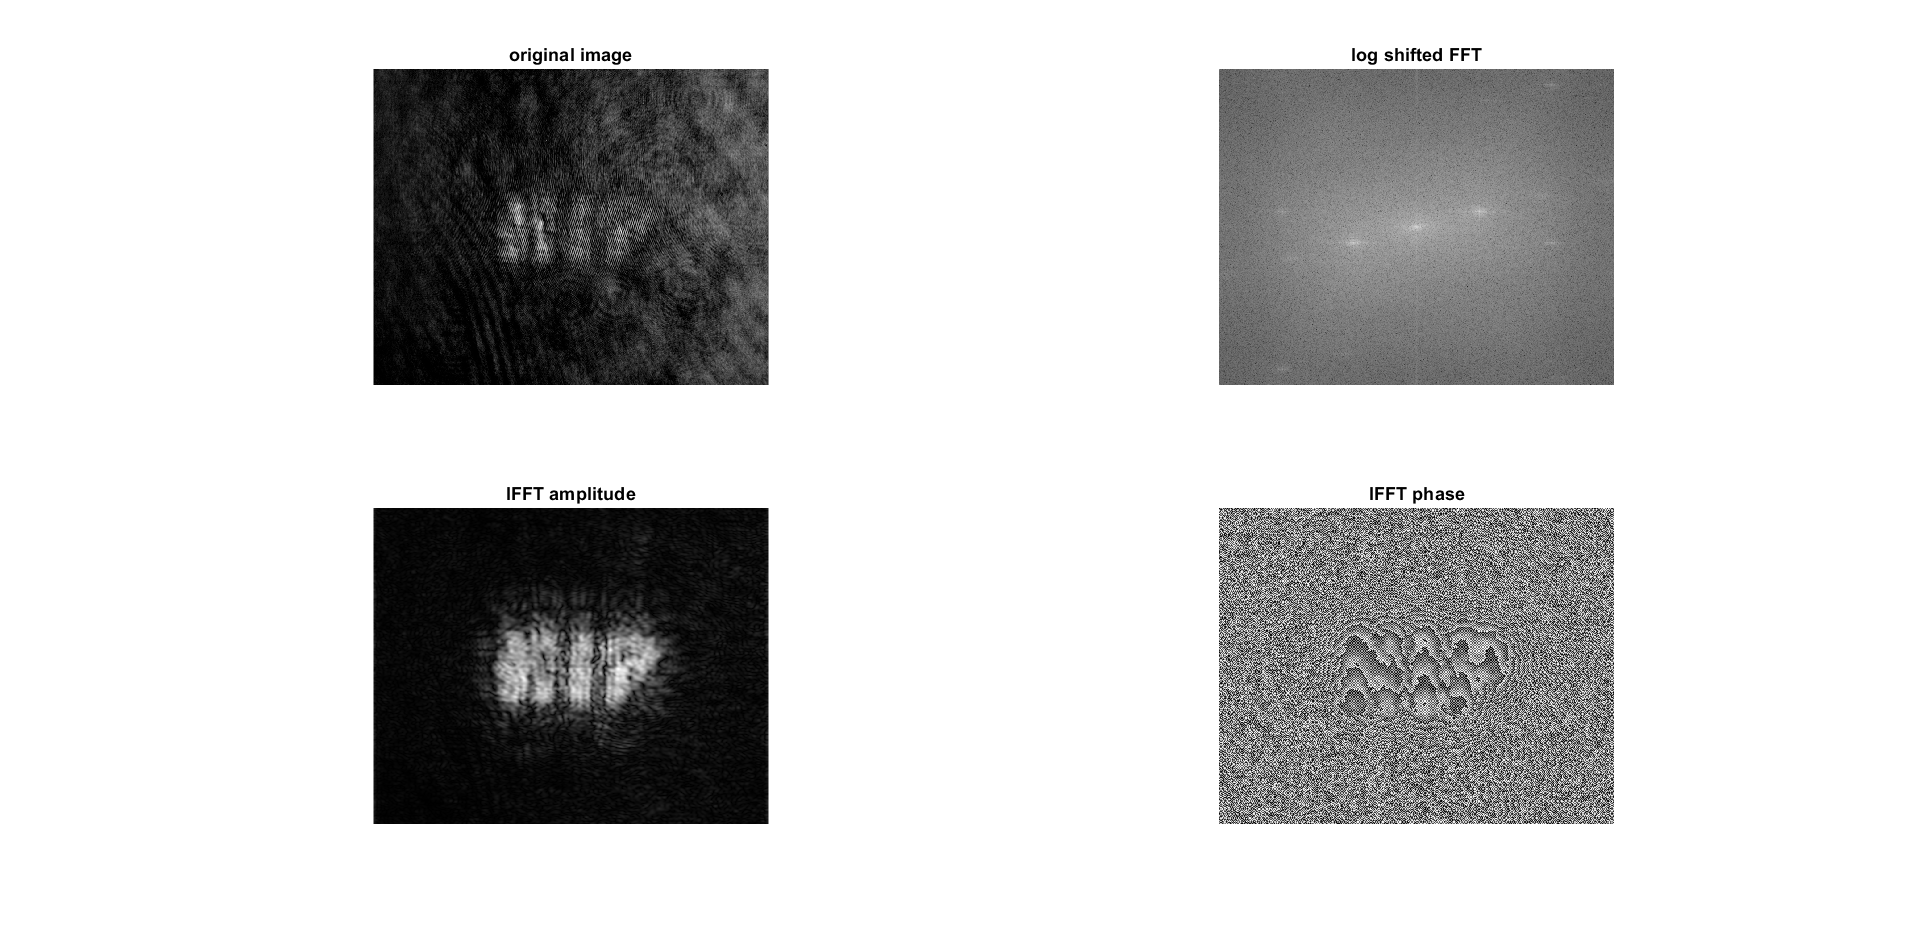

%display 
subplot(2,2,1);
imshow(I); title("original image");
subplot(2,2,2);
imagesc(log(abs(Ifft))); axis image; axis off; title("log shifted FFT");
subplot(2,2,3);
imagesc(abs(Ifft_inv)); axis image; axis off; title("IFFT amplitude");
subplot(2,2,4);
imagesc(angle(Ifft_inv)); axis image; axis off; title("IFFT phase");

saveas(gcf, "final", 'png');

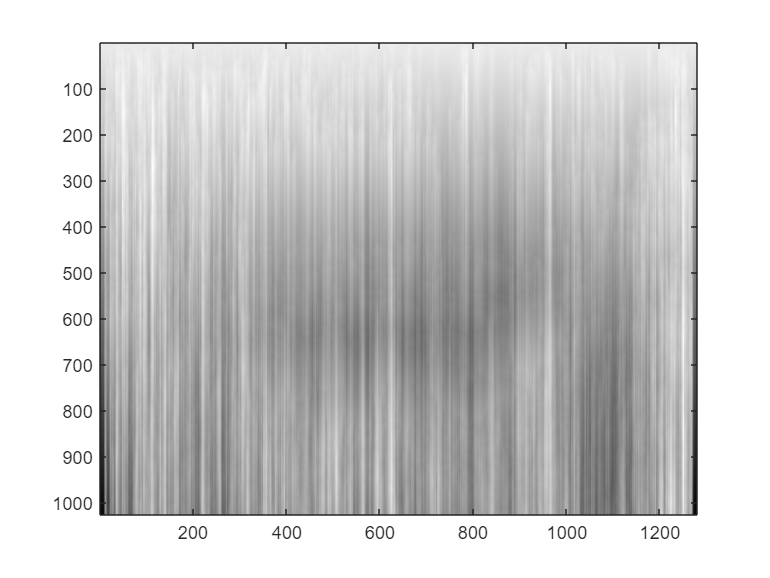

%unwrapping angle 
unwrap_angle = unwrap(angle(Ifft_inv));
figure; imagesc(unwrap_angle); colormap gray;

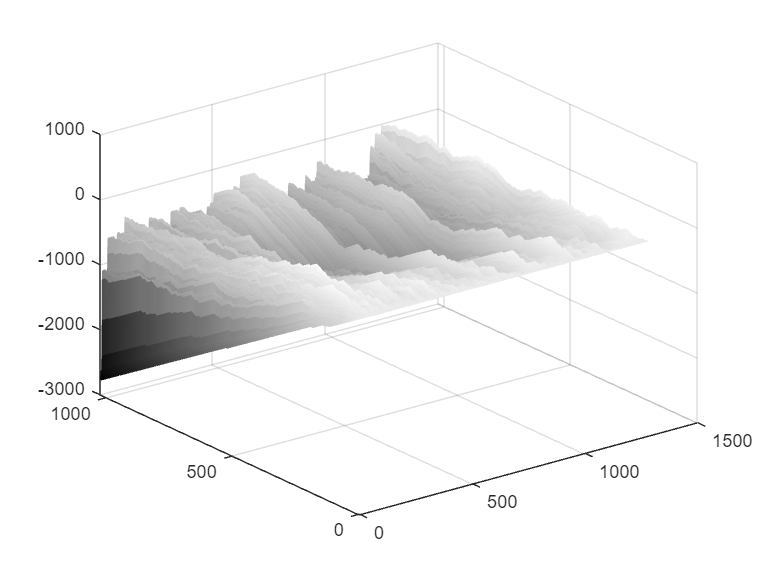

mesh(unwrap_angle);